# The Spectral Factorization Algorithm

## Introduction

This live function introduces and explains the spectral factorisation algorithm, as well as implementing it.

## The Spectral Factorization Theorem

Given a process with rational spectrum $\Phi(z)\,$, there exists one and only one representation of the process as the output of an LTI system driven by a white process $\eta(\cdot)$ and with transfer function $W(z) = \frac{N(z)}{D(z)}$  if the following conditions are imposed on $W(z)\,$:

- $N(z)\,$ and $D(z)\,$ monic, co-prime and of the same degree;

- all roots of $N(z)\,$ (zeros of $W(z)\,$ ) have $\vert \,\cdot\,\vert \le 1\,$; 

- all roots of $D(z)\,$ (poles of $W(z)\,$ ) have $\vert \,\cdot\,\vert < 1\,$.


$$\Phi_{y}(z) = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot \Phi_{\eta}(z) =  W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot \lambda^2_{\eta}$$


## **A Stationary Stochastic Process from a White Noise Response of an LTI Filter **

## 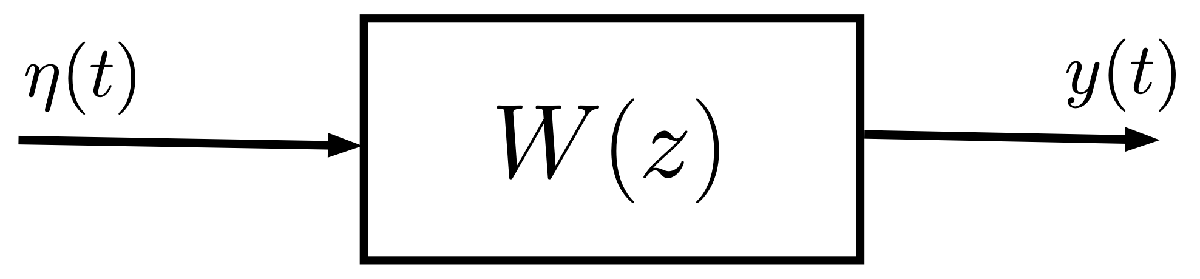

Consider a stationary stochastic process $y(t)$, generated by an LTI dynamic system with a generic transfer function			

		
$$W(z) = \displaystyle \frac{b(z)}{a(z)} = \displaystyle \frac{b_0\, z^n+b_1\, z^{n-1} + \cdots +b_{n-1} \, z+b_n}{z^n+a_1 \, z^{n-1} + \cdots +a_{n-1}\, z +a_n} $$


and white noise $\eta(t)$ as its input.  Assuming that the LTI system $W(z)$ is BIBO stable. the power spectrum of the output stationary stochastic process is


$$\begin{array}{rcl}
\Phi_{y}(z) &=& \displaystyle W(z) \cdot W\left(z^{-1}\right) \cdot \lambda^2_{\eta} = \displaystyle \frac{b(z)}{a(z)} \cdot \frac{b\left(z^{-1}\right)}{a\left(z^{-1}\right) }\cdot \lambda^2_{\eta} \\
 &=& \displaystyle \frac{b_0\, z^n+b_1\, z^{n-1} + \cdots +b_{n-1} \, z+b_n}{z^n+a_1 \, z^{n-1} + \cdots +a_{n-1}\, z +a_n}  \cdot   
 \displaystyle \frac{b_0\, z^{-n}+b_1\, z^{-(n-1)} + \cdots +b_{n-1} \, z^{-1}+b_n}{z^{-n}+a_1 \, z^{-(n-1)} + \cdots +a_{n-1}\, z^{-1} +a_n} 
\cdot  \lambda^2_{\eta} \\
 &=& \displaystyle \frac{\beta_0+\beta_1\,\left(z+z^{-1}\right)+ \cdots + \beta_n\,\left(z^n+z^{-n}\right)}{1+\alpha_1\,\left(z+z^{-1}\right)+\cdots + \alpha_n\,\left(z^n+z^{-n}\right)} = \displaystyle \frac{\beta(z)}{\alpha(z)}
\end{array}$$


where


$$\left\{
\begin{array}{rclll}
\alpha_i &=& \displaystyle \frac{\displaystyle \sum_{k=0}^{n-1} a_k\,a_{k+i}}{\displaystyle \sum_{k=0}^{n} a_k^2} &,& i=1,\,2,\,\ldots ,\,n \\
\\
\beta_j &=& \displaystyle \frac{\displaystyle \sum_{k=0}^{n-1} b_k\,b_{k+j}}{\displaystyle \sum_{k=0}^{n} a_k^2} \cdot \lambda^2_{\eta} &,& j=1,\,2,\,\ldots ,\,n 
\end{array}
\right.$$


### Remark

Note the peculiar structure of the polynomials $\beta(z)$ and $\alpha(z)$ in the expression of the spectrum. They are **symmetric polynomials** in the variables $z$ and $z^{-1}$ . In fact, permuting the variable $z$ with $z^{-1}$ does not change the expression of both the polynomials.

The feature just highlighted is in fact a peculiar property of rational spectra: one can always write the two polynomials $\beta(z)$ and $\alpha(z)$ that appear in the spectrum $\Phi_y(z)$ as symmetrical polynomials in $z$ and $z^{-1}$.


function [r,Cz, Az] = L8_spectrFactAlg(betaP, alphaP)
%  The function L8_spectrFactAlg() allows 
% the spectral factorisation of a rational 
% spectrum to be calculated.
% ---
% Inputs:
% betaP  <--> the coefficients of the symmetric polynomial beta(z+z^(-1)),
%             ordered from beta_n to beta_0
% alphaP <--> the coefficients of the symmetric polynomial alpha(z+z^(-1)),
%             ordered from alpha_n to alpha_0 (=1)
% ---
% Outputs:
% Az <--> the monic Hurwitz polynomial 1+a_1 z^(-1)+...a_n z^(-n_) -- the
%         roots of Az have magnitude stricly less than 1
% Cz <--> the monic polynomial 1+c_1 z^(-1)+...c_n z^(-n_); the roots of Cz
%         have magnitude less or equal to 1
% r  <--> the variance of the white noise feeding-in the filter with
%         transfer function W(z) = Cz/Az

[r2, Cz] = poly_spectral_fact(fliplr(betaP)); % spectral factorization of teh symmetric polynomial beta(z)

[r1, Az] = poly_spectral_fact(fliplr(alphaP)); % spectral factorization of teh symmetric polynomial alpha(z)

r = r2/r1; % the computation of the white noise variance


end


### The Spectral Factorization Algorithm: a Summary

Given the rational spectrum 


$$\Phi(z) = \displaystyle \frac{\beta(z)}{\alpha(z)} = \displaystyle \frac{\displaystyle \sum_{k=-m}^{m}\, \beta_k\,z^k}{\displaystyle \sum_{k=-n}^{n}\,\alpha_k\,z^k}$$


with


$$\left\{
\begin{array}{lcl}
\alpha_p = \alpha_{-p} &\quad& p=-n\,,\,-n+1\,,\, \cdots ,\, n-1\,,\, n \\
\beta_q = \beta_{-q} &\quad& q=-m\,,\,-m+1\,,\, \cdots ,\, m-1\,,\, m \\
\alpha_n \ne 0 \,,\; \beta_m \ne 0 &\quad& \text{i.e. both polynomials are symmetric polynomials in $z$ and $z^{-1}$} \\
\Phi\left(e^{i\,\omega} \right) \ge 0 \; \forall \omega& \quad &\text{i.e. $\Phi(z)$ is a rational spectrum}
\end{array}
\right.$$


then there is only one factorization of the spectrum $\Phi(z)$ such that


$$\Phi(z) = \displaystyle \frac{C(z)}{A(z)} \cdot \frac{C\left(z^{-1}\right)}{A \left(z^{-1}\right)} \cdot r$$


with


$$\left\{
\begin{array}{rcl}
r &>& 0 \\
A(z) &=& 1+a_1\,z^{-1}+a_2\,z^{-2}+\cdots+a_n\,z^{-n} \quad \text{with } z_p: A(z_p) = 0 \,,\; \vert z_p \vert <1 \; \forall p \\
C(z) &=& 1+c_1\,z^{-1}+c_2\,z^{-2}+\cdots+c_m\,z^{-m} \quad \text{with } z_q: C(z_q) = 0 \,,\; \vert z_q \vert \le 1 \; \forall q 
\end{array}
\right.$$


**First step of the algorithm: **exploiting the fact that both $\alpha(z)$ and $\beta(z)$ are symmetric polynomials, factor both the polynomials 


$$\left\{
\begin{array}{rcl}
\alpha(z) &=& r_1\, A(z)\, A\left(z^{-1}\right) \\
\beta(z) & =& r_2\, C(z)\, C\left(z^{-1}\right)
\end{array}
\right.$$


where $r_1>0$, $r_2>0$ and the polynomials $A(z)$ and $C(z)$ are monic polynomials as defined above.

**Second step of the algorithm**: the spectral factorization of $\Phi(z)$ is 


$$\Phi(z) = \displaystyle \frac{\beta(z)}{\alpha(z)} = \left( \frac{r_2}{r_1} \right)\cdot \left[ \frac{C(z)}{A(z)} \right] \cdot \left[\frac{C\left(z^{-1}\right)}{A\left(z^{-1}\right)} \right] = r \cdot W(z) \cdot W\left(z^{-1}\right)$$


### An Insight on the Algorithm's Details: The Spectral Factorization of a Symmetric Polynomial

Given a symmetric polynomial


$$P(z) = p_0+p_1\,\left(z+z^{-1}\right)+\cdots\,+ p_n\,\left(z^n+z^{-n}\right) = p_0+\displaystyle \sum_{k=1}^{n} \, p_k\,\left(z^k+z^{-k}\right)\,,\quad p_n \ne 0$$


such that $p\left(e^{i\,\omega}\right) \ge 0 \; \forall \omega$, then there is one and only one factorization of $p(z)$ as


$$p(z) = r\,q(z)\,q\left(z^{-1}\right)$$


with

- 
$$r>0$$


- 
$$q(z) = 1+q_1\,z^{-1}+\cdots+q_n\,z^{-n} = \displaystyle 1+\sum_{k=1}^{n}\,q_k\,z^{-k}$$
 

The roots of $q(z)$ are such that 

- if $p\left(e^{i\,\omega}\right) \ge 0 \; \forall \omega$, then $\vert z_j\vert \le 1\; \forall z_j: q(z_j) =0$

- if $p\left(e^{i\,\omega}\right) > 0 \; \forall \omega$, then $\vert z_j\vert < 1\; \forall z_j: q(z_j) =0$

**Sketch of the algorithm**:

- given $p(z)$ build the palindromic polynomial $\rho(z) = z^n\,p(z) = p_0\,z^n + \displaystyle \sum_{k=1}^{n}\, p_k\,\left(z^{n+k}+z^{n-k}\right)$

- compute the $2n$ roots of the polynomial $\rho(z)$; $\rho(z)$ is a palindromic polynomial (by construction) so if $\tilde z$ is a root of $\rho(z)$ then also $\tilde{z}^{-1}$ is a root of $\rho(z)$, and with the same multiplicity;

- factor the polynomial $\rho(z)$ as


$$\rho(z) = p_n \displaystyle \prod_{\vert z_k \vert \le 1} \, (z-z_k) \, \prod_{\vert z_k \vert \le 1} \left(z-z_k^{-1} \right) $$


- consequently, the factorization of $p(z)$ assumes the expression


$$p(z) = z^{-n}\,\rho(z) = \displaystyle \frac{(-1)^n\,p_n}{\displaystyle \prod_{k=1}^{n}\, z_k} \cdot \displaystyle \prod_{k=1}^{n}\, \left(1-z_k\,z^{-1}\right) \, \cdot \prod_{k=1}^{n} \left(1-z_k\,z\right) \;,\qquad \vert z_k\vert \le 1 \; \forall k$$


- finally


$$r = \displaystyle \frac{(-1)^n\,p_n}{\displaystyle \prod_{k=1}^{n}\, z_k}\;, \qquad q(z) = \displaystyle \prod_{k=1}^{n}\, \left(1-z_k\,z^{-1}\right)\;, \qquad \vert z_k\vert \le 1 \; \forall k
$$


function [r, q] = poly_spectral_fact(p)
    % The function computes the spectral factorization 
    %                  p(z)=rq(z)q(z^-1) 
    % of the symmetric polynomial p(z) such that 
    % q(z) = 1 + ... + qn z^(-n) is the unique monic spectral factor with
    % all the roots inside the circle |z|<=1

    n = length(p)-1; % the degree of p(z)
    rho = [p(n+1:-1:2) p]; % building the polynomial rho(z)

    z = roots(rho); % finding the roots of rho(z)
    z = complex(z);

    [~,i] = sort(abs(z)); % sorting the roots in ascending order, according to the magnitude
    z = z(i); % applying the sorting criterion

    z = z(1:n); % now the first n roots have magnitude less or equal to 1
                % (whereas the remaining roots have magnitude greater than 1)
    q = poly(z); % build the q(z) polynomial using the roots with |z|<=1

    r = ((-1)^n)*rho(1)/prod(z); % evaluating the numerical constant r
end